**newton's fractal generator**

insert a polynomial (with complex roots):

colormap('cool')
polynomial = [5 1 0 3 0];
polynomial_differentiated = polyder(polynomial);
polynomial_roots=roots(polynomial);
number_of_roots=size(polynomial_roots);
number_of_roots=number_of_roots(1,1);
left_limit=-3;
right_limit=3;
upper_limit=4;
lower_limit=0;
resolution=0.01;
n=10;
x_values=[];
y_values=[];
colour_values=[];

this bit sets up a loading bar for more detailed renders

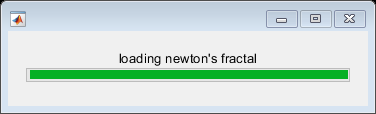

loading_counter=0;
number_of_points=(abs(right_limit-left_limit)/resolution)*(abs(upper_limit-lower_limit)/resolution);
f=waitbar(loading_counter/number_of_points,"loading newton's fractal");

setting up a range of points to work n iterations of netwon-raphson method upon

for x = left_limit:resolution:right_limit
    for y = lower_limit:resolution:upper_limit
        z0 = complex(x,y);
        loading_counter=loading_counter+1;
        format short
        waitbar(loading_counter/number_of_points,f)
        for i = 0:1:n-1
            pz=polyval(polynomial,z0);
            pz_diff=polyval(polynomial_differentiated,z0);
            z1=z0-(pz/pz_diff);
            z0=z1;

distances to roots are now checked and depending on closest root a colour is assigned to that point and it is plotted

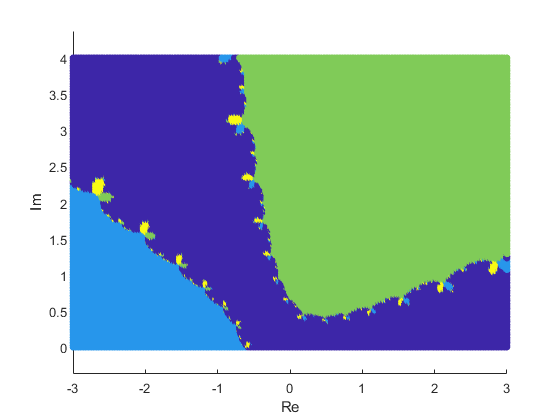

        end
   
        smallest_distance=30*polynomial(1);
        for i=1:number_of_roots
            current_point=[real(z0) imag(z0)];
            current_root=[real(polynomial_roots(i,1)) imag(polynomial_roots(i,1))];
            d=norm(current_point-current_root);
            if d<=smallest_distance
                smallest_distance=d;
                closest_root=i;
            end
        end
        colour_values=[colour_values closest_root];
        x_values=[x_values x];
        y_values=[y_values y];
    end     
end
f=figure('Name',"Newtons fractal");
scatter(x_values,y_values,25,colour_values,'filled')
axis equal
xlabel('Re')
ylabel('Im')